# Práctica 5. Métodos monopaso para EDOs

El objetivo de esta práctica es implementar y probar diferentes métodos monopaso para resolver la ecuación


$$\mathrm{(PVI)} \qquad \begin{cases}
\frac{d\mathbf{u}}{dt} (t) = \mathbf f (t, \mathbf u (t)) & t \in [t_0, T], \\
\mathbf u(t_0) = \mathbf u_0 
\end{cases}$$


## 1. Implementación de los métodos 

### 1.a. Ecuaciones vectoriales

Implementar los diferentes métodos estudiados en teoría. 

#### 1.a.1. Método del trapecio o de Crank-Nicolson.

Escribir en el Apéndice A1 una función implemente el método del trapecio (o de Crank-Nicolson) para la ecuación (PVI) y que responda a la sintaxis

    `[t,U]=CrankNicolson(f,t_interv,u_0,N)`

#### 1.a.2. Runge-Kutta 4.

Escribir en el Apéndice A2 una función implemente el explícito Runge-Kutta 4 dado por las ecuaciones


$$		\mathbf U_{i+1} = \mathbf  U_i + \frac h 6 \left( \mathbf F_1 + 2\mathbf  F_2 + 2\mathbf F_3 + \mathbf  F_4 \right) \\
		\mathbf  F_1 = \mathbf  f(t_i, \mathbf  U_i) \\
		\mathbf  F_2 = \mathbf  f \left( t_i + \frac h 2, \mathbf  U_i + h\frac {\mathbf  F_1}2   \right)\\
		\mathbf  F_3 =\mathbf  f \left(t_i + \frac h 2,  \mathbf U_i + h\frac {\mathbf  F_2}{2} \right)\\
		\mathbf  F_4 = \mathbf  f \,\left(  t_{i} + h, \mathbf  U_i + h\mathbf  F_3 \right) $$


 para la ecuación (PVI) y que responda a la sintaxis

    `[t,U]=RK4(f,t_interv,u_0,N)`

### 1.b. Comprobando la convergencia en el caso escalar

Probar los diferentes métodos contra la función $f(t,u) = u$ y $u(0) = 1$. La solución explícita de esta ecuación es $u(t) = e^t.$

Utilizar $T = 5, h = 2,1,0.5,0.1,0.05,0.01,0.005,0.001$

Calcular el error absoluto, y representarlo en un gráfica $(\log h, \log \varepsilon (h))$. Usando ajuste lineal de los valores de h próximos a 0, comprobar que $\varepsilon(h) = O(h^p)$

#### 1.b.1 Crank-Nicolson

#### 1.b.2. RK4

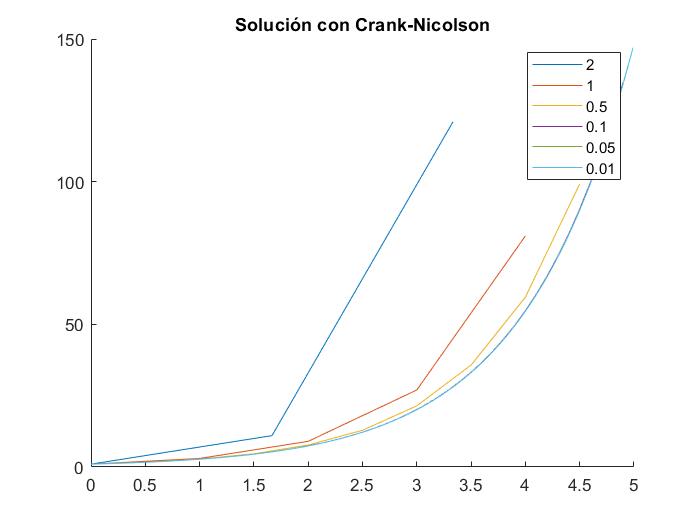

% Escribimos los datos que no varían:
f = @(t,u) u;
t_interv = [0, 5];
u_0 = 1;

% Escribimos el vector h donde estarán los 'pasos':
h = [2, 1, 0.5, 0.1, 0.05, 0.01, 0.005, 0.001];

% Definimos el vector de los errores máximos:
epsmax = zeros(6,1);

hold on
for i = 1:6
    
    N = round(5 / h(i));
    
    % Ahora ya podemos aplicar la función que calculará t y U:
    
    [t,U] = CrankNicolson(f,t_interv,u_0,N);
    
    % Ahora debemos calcular el error absoluto y representarlo en una
    % gráfica (log(h), log(eps(h))):
    
    for j = 1:N
        
        % Calculamos los eps_j sabiendo que ya hemos calculado os U_j y
        % 'calculando' los u(t_j), conociendo los t_j (calculados con la 
        % función anterior al igual que los U_j):
        
        eps = abs(U(j) - exp(t(j)));
        
        if (epsmax(i) < eps)
            
            epsmax(i) = eps;
         
        end

    end
    
    plot(t,U) 
    
end

% El método para pasos más pequeños tarda mucho por el comando vpasolve
title('Solución con Crank-Nicolson')
legend('2','1','0.5','0.1','0.05','0.01')
hold off

Representamos el error

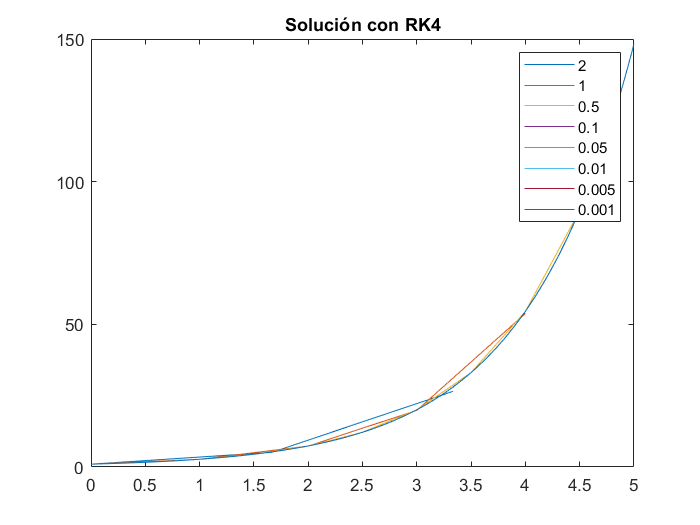

% AHORA HACEMOS RK4

% Escribimos los datos que no varían:
f = @(t,u) u;
t_interv = [0, 5];
u_0 = 1;

% Escribimos el vector h donde estarán los 'pasos':
h = [2, 1, 0.5, 0.1, 0.05, 0.01, 0.005, 0.001];

% Definimos el vector de los errores máximos:
epsmax2 = zeros(8,1);


for i = 1:8
    
    N = round(5 / h(i));
    
    % Ahora ya podemos aplicar la función que calculará t y U:
    
    [t,U] = RK4(f,t_interv,u_0,N);
    
    % Ahora debemos calcular el error absoluto y representarlo en una
    % gráfica (log(h), log(eps(h))):
    
    for j = 1:N
        
        % Calculamos los eps_j sabiendo que ya hemos calculado os U_j y
        % 'calculando' los u(t_j), conociendo los t_j (calculados con la 
        % función anterior al igual que los U_j):
        
        eps2 = abs(U(j) - exp(t(j)));
        
        if (epsmax2(i) < eps2)
            
            epsmax2(i) = eps2;
         
        end

    end
    
    plot(t,U) 
    hold on
end

% El método para pasos más pequeños tarda mucho por el comando vpasolve
title('Solución con RK4')
legend('2','1','0.5','0.1','0.05','0.01','0.005','0.001')
hold off

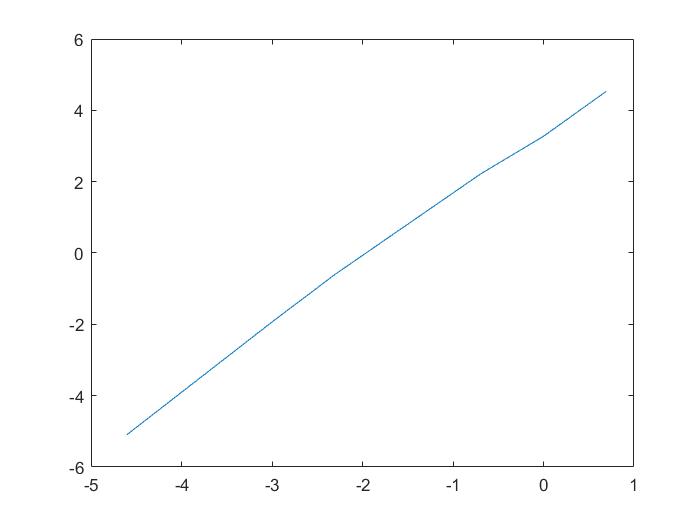



% Ponemos los errores de ambos
hcn = h(1:6);
plot(log(hcn), log(epsmax))


% Para Crank-Nicolson no podemos hacer el ajuste lineal para valores
% cercanos a cero por lo que explicamos anteriormente

plot(log(h), log(epsmax2))
hold on

Parece lineal. Ajustamos su comportamiento:

haux = h(4:8)

haux =     0.1000    0.0500    0.0100    0.0050    0.0010


E = epsmax2(4:8)'

E = 	1.0e+-3 *

    0.5046    0.0349    0.0001    0.0000    0.0000


P = polyfit(log(haux),log(E),1);
P(1)

ans = 3.7801

P(2)

ans = 0.9756

Efectivamente, $\log(h) \approx 3,98 \log(\varepsilon(h))+1,12 = \log( C \varepsilon(h)^{3.8})$

Representamos el ajuste

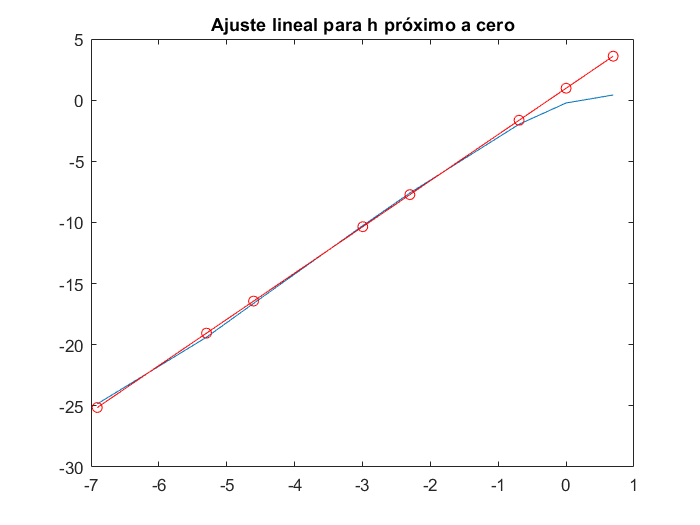

log_err_fit =  P(1) * log(h) + P(2);
plot(log(h),log_err_fit,'-or')
title('Ajuste lineal para h próximo a cero')
hold off

## 2. Un problema de persecución

Dado un sujeto a ser perseguido, de posición $\mathbf x (t) \in \mathbb R^2$, un perseguidor de posición $\mathbf u(t)$ a velocidad constante $v$, que se dirija siempre hacia su perseguido tendrá por trayectoria la solución del problema de valor inicial


$$\begin{cases}
\frac{d\mathbf{u}}{dt} = v \frac{\mathbf x - \mathbf u}{\|\mathbf x - \mathbf u \|} \\
\mathbf u(0) = \mathbf u_0
\end{cases}$$


Si se produce alcance $\mathbf u (t) = \mathbf x (t) $ se debe dar un aviso. Escribir la cinética en el Apéndice B. Utilizar RK4 con paso $h=0.01$

La solución analítica de este problema (incluso cuando $\mathbf x$ es un movimiento rectilíneo uniforme), es muy complicada. 

Representar lo que sucede con diferentes trayectorias del perseguido a velocidad constante, y diferentes valores de $v
$ ¿qué parece deducirse?


%SUPONEMOS UN MRU EN EL EJE Y A VELOCIDAD 3 PARTIENDO DE (0,0) PARA LA PRESA
vp=3;
tp=0:0.01:10;
xp=zeros(1,length(tp));
yp=tp*vp;
X=[xp',yp'];
%SUPONEMOS UNA POSICIÓN INICIAL (5,0) Y VELOCIDAD 5 PARA EL DEPREDADOR
u_0=[5,0];
interv=[0,10];
vd=5;
N=length(tp);
f=@(t,x,u)[5*(x(1)-u(1))/(sqrt((x(1)-u(1))^2+(x(2)-u(2))^2)),5*(x(2)-u(2))/(sqrt((x(1)-u(1))^2+(x(2)-u(2))^2))];
[t,U,i]=Persecucion(f,interv,u_0,N,X);

msg = 'el depredador alcanza a la presa en el punto:'

ans =     0.0000    4.7089


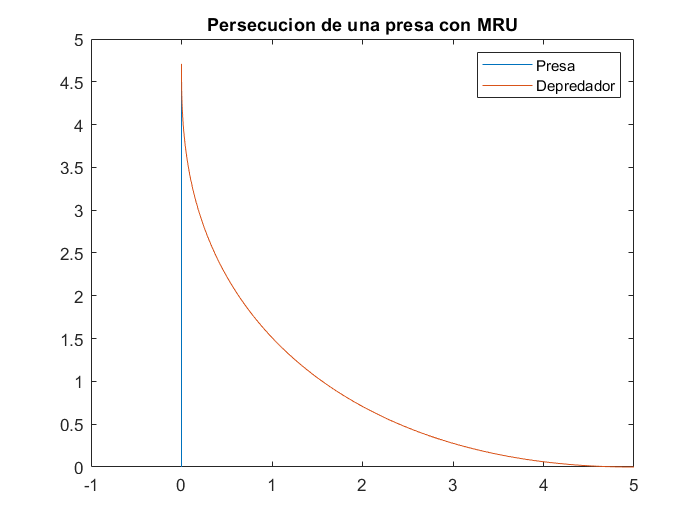

plot(xp(1:i),yp(1:i),U(:,1),U(:,2))
legend('Presa','Depredador')
title('Persecucion de una presa con MRU')

## 3. Diagramas de fase: ecuación del péndulo

Estudiar la ecuación


$$\begin{cases}
m L \theta '' (t) + 2 L \beta \theta' (t) + mg \sin (\theta(t)) = F & t \in [0,T] \\
\theta(0) = \theta_0, \\
\theta' (0) = w_0.
\end{cases}$$


Se consideran los valores $m = 1 [kg] , g = 9.8 [m/s^2], T = 10.$

**3.1.a. Estudiar, para **$F= 0, L = 1 [m]$**, los diferentes comportamientos del sistema con **$\beta = 0, 0.25, 1.5$ **partiendo del dato inicial **$\theta_0 = 0, w_0 = 0.5$. **Representar tanto **$(t, \theta(t))$ **como el diagrama de fase** $(\theta, \dot \theta)$

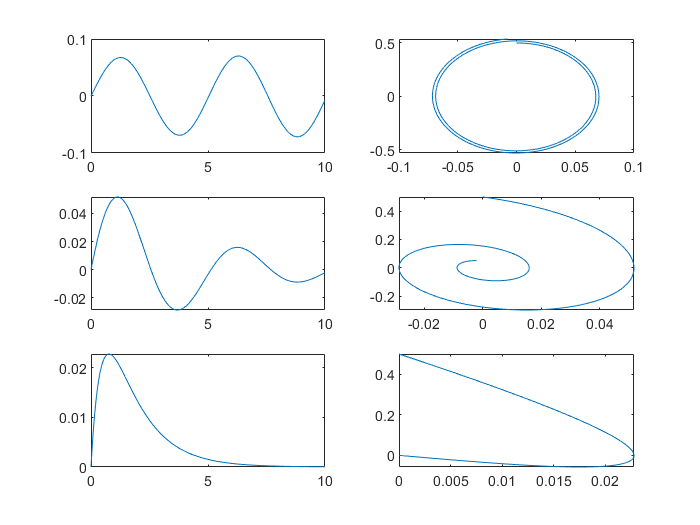

% Primero escribimos los valores que no varían:
clear all
t_interv = [0, 10];
u_0 = [0; 0.5];

% Ahora escribimos el vector h donde estarán los 'pasos' y también
% escribimos el vector beta donde estarán los diferentes valores que este
% parámetro tomará:
h = 0.01;
beta = [0, 0.25, 1.5];

count = 1;

    
N = (t_interv(2) - t_interv(1)) / h;
    
% Tenemos distintas funciones f dependiendo del parámetro beta luego:

for j = 1:3
         
    f = @(t,U1,U2) (-2 * beta(j) * U2 - 9.8 * U1);
       
    % Ahora ya podemos aplicar la función que calculará t y U mediante RK4:
        
    t_0 = t_interv(1);
    T = t_interv(2);
    h = (T-t_0)/N;
        
    t(1) = t_0;
    U(:, 1) = u_0;
        
    for k = 1 : N-1
            
        t(k+1) = t(k) + h;
            
        F1 = f(t(k), U(1,k), U(2,k));
           
        F2 = f(t(k) + h/2, U(1,k) + h * F1/2, U(2,k) + h * F1/2);
            
        F3 = f(t(k) + h/2, U(1,k) + h * F2/2, U(2,k) + h * F2/2);
            
        F4 = f(t(k) + h, U(1,k) + h * F3, U(2,k) + h * F3);
            
        % Como en la práctica 4
            
        U(:,k+1) = U(:,k) + h/6 * [U(2,k); (F1 + 2 * F2 + 2 * F3 + F4)];
    end
       
    % Ya solo nos falta pintar la gráfica y el diagrama de fases:
    subplot(3,2,count)
    plot(t,U(1,:))
    count = count + 1;
       
    subplot(3,2,count)
    plot(U(1,:), U(2,:))
    count = count + 1;
end

**3.1.b. Comparar, considerando **$F = 0$**, con el problema linealizado**


$$\begin{cases}
m L \theta '' (t) + 2 L \beta \theta' (t) + mg \theta(t) =0 & t \in [0,T] \\
\theta(0) = \theta_0, \\
\theta' (0) = w_0.
\end{cases}$$


**Considerar **$\beta = 0.25$ **y las condiciones iniales **$w_0 = 0, \theta_0 = 0.25, 0.5, 1, 2, \pi - 0.1$

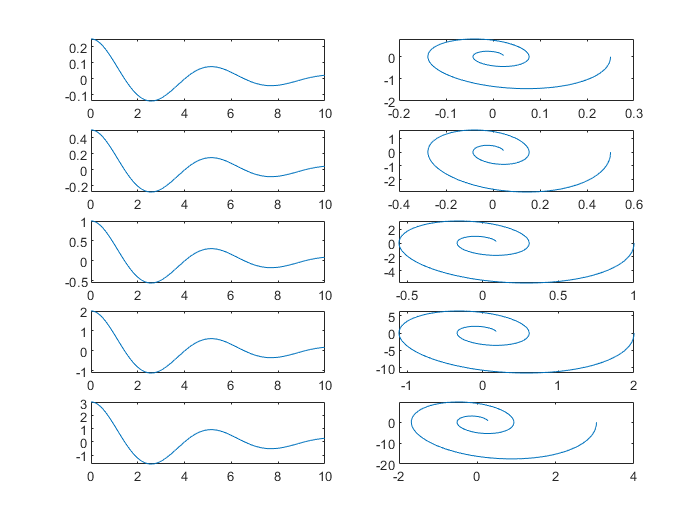

% Primero escribimos los valores que no varían:

t_interv = [0, 10];

% Ahora escribimos el vector h donde estarán los 'pasos'y también
% escribimos el vector beta donde estarán los diferentes valores que este
% parámetro tomará:
h = 0.01;
beta = 0.25;
teta_0 = [0.25, 0.5, 1, 2, pi-0.1];

count = 1;

for i = 1 : 5
    
    u_0 = [teta_0(i); 0];
  
    N = (t_interv(2) - t_interv(1)) / h;
    
    % Tenemos distintas funciones f dependiendo del parámetro beta luego:
        
    f = @(t,U1,U2) (-2 * beta * U2 - 9.8 * U1);
       
    % Ahora ya podemos aplicar la función que calculará t y U mediante RK4:
        
    t_0 = t_interv(1);
    T = t_interv(2);
    h = (T-t_0)/N;
        
    t(1) = t_0;
    U(:, 1) = u_0;
        
    for k = 1 : N-1
            
        t(k+1) = t(k) + h;
            
        F1 = f(t(k), U(1,k), U(2,k));
            
        F2 = f(t(k) + h/2, U(1,k) + h * F1/2, U(2,k) + h * F1/2);
            
        F3 = f(t(k) + h/2, U(1,k) + h * F2/2, U(2,k) + h * F2/2);
            
        F4 = f(t(k) + h, U(1,k) + h * F3, U(2,k) + h * F3);
            
        % Como en la práctica 4
            
        U(:,k+1) = U(:,k) + h/6 *[U(2,k); (F1 + 2 * F2 + 2 * F3 + F4)];
    end
    
    % Ya solo nos falta pintar la gráfica y el diagrama de fases:
    subplot(5,2,count)
    plot(t,U(1,:))
    count = count + 1;
       
    subplot(5,2,count)
    plot(U(1,:), U(2,:))
    count = count + 1;
   
end

## Apéndice A. Métodos vectoriales

### A1. Método de Crank-Nicolson

function [t,U]=CrankNicolson(f,t_interv,u_0,N)
  
  % Conocemos el tiempo inicial t_0 (t_interv(1)) y el tiempo final
  % T (t_interv(2))

  t_0 = t_interv(1);
  T = t_interv(2);

  % También conocemos la función f y el número de pasos N.
  % Además sabemos el valor inicial u_0

  % Calculamos el paso h:
  h = (T - t_0) / N;

  % Inicializamos el vector U donde meteremos los U_i
  U = zeros(N,1);
  U(1) = u_0;

  % También inicializamos el vector T donde metemos los t_i, siendo 
  % el t_0 el primero.
  t = zeros(N,1);
  t(1) = t_0;
  
  % Definimos la variable x que utilizaremos para calcular U(i+1)
  syms x
  
  for i = 1 : (N-1)
      
      t(i+1) = t(i) + h;
      
      % Hay que calcular U(i+1) resolviendo ecuaciones implícitas
      
      ec_vec = x == U(i) + (h/2) * (f(t(i), U(i)) + f(t(i+1), x));
      U(i+1) = vpasolve(ec_vec, x);
      
  end
end

### A2. Método de Runge-Kutta 4

function [t,U]=RK4(f,t_interv,u_0,N)
  
  % Conocemos el tiempo inicial t_0 (t_interv(1)) y el tiempo final
  % T (t_interv(2))

  t_0 = t_interv(1);
  T = t_interv(2);

  % También conocemos la función f y el número de pasos N.
  % Además sabemos el valor inicial u_0

  % Calculamos el paso h:
  h = (T - t_0) / N;

  % Inicializamos el vector U donde meteremos los U_i
  U = zeros(N,1);
  U(1) = u_0;

  % También inicializamos el vector T donde metemos los t_i, siendo 
  % el t_0 el primero.
  t = zeros(N,1);
  t(1) = t_0;
  
  for i = 1 : (N-1)
      F1 = f(t(i), U(i));
      F2 = f(t(i) + (h/2), U(i) + h * (F1 / 2));
      F3 = f(t(i) + (h/2), U(i) + h *(F2 / 2));
      F4 = f(t(i) + h, U(i) + h * F3);
      
      U(i+1) = U(i) + (h/6) * (F1 + 2 * F2 + 2 * F3 + F4);
      t(i+1) = t(i) + h;
  end
  
end

### Apéndice B. Función de persecución

function [t,U,i]=Persecucion(f,t_interv,u_0,N,X)
    n=length(u_0);
    h=((t_interv(2)-t_interv(1))/N);
    U(1,:)=u_0;
    t(1)=t_interv(1);
    for i=1:N
        if norm(U(i,:)-X(i,:))>0.01
            t(i+1)=t(i)+h;
            U(i+1,:)= U(i,:)+h*f(t(i),X(i,:),U(i,:));
        else
            msg='el depredador alcanza a la presa en el punto:';
            msg
            U(i,:)
            break
        end
    end
end
